# Example For plotpp

### 1. Attractor

In the first example, we only need one single command to get the phase portrait.

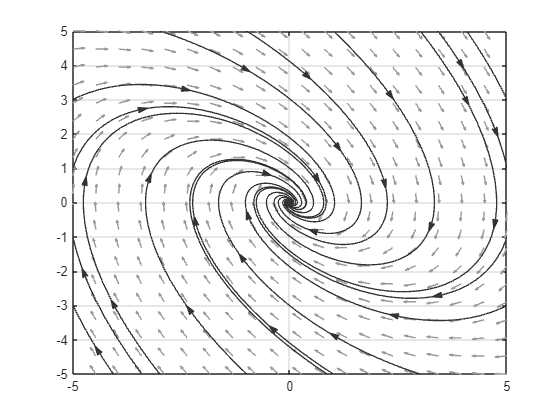

plotpp(@(t,x)[x(2);-x(1)-1*x(2)])

### 2. Van der Pol Oscillator

In the second example, we plot the phase portrait of the van der Pol equation:


$$\begin{cases}
\dot{x}_1 =x_2 \\
\dot{x}_2=-x_1+\varepsilon(1-x_1^2)x_2
\end{cases}$$


We set the time span to 20 second, which is a proper time for demonstration, by trail and error.  And we changed the color of quiver and lines to have a nice look.

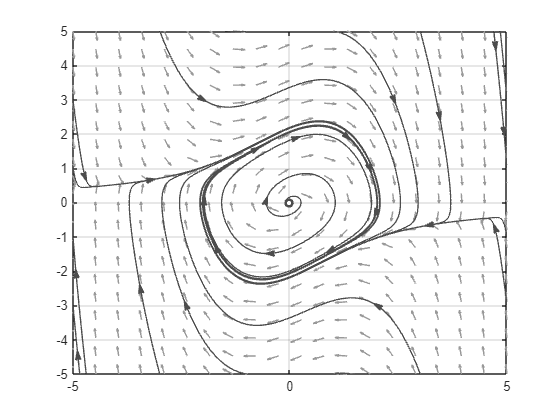

odefun = @(t, x) [x(2); -x(1) + 0.5*(1 - x(1)^2)*x(2)];
plotpp(odefun,'tspan', 30,...
                      'quivercolor', [0.6,0.6,0.6],...
                      'linecolor', [0.3,0.3,0.3])

### 3. Swing Equation with Damping

The third one is the swing equation:


$$\begin{cases}
\dot{\delta}=\omega \\
\dot{\omega}=a-\sin\delta-D\omega
\end{cases}$$


We only want to plot the trajectories from the saddle, so that we could know where the region of attraction (ROA) is. Therefore, we set the input argument '*plotNonSaddleTrajectory*' be *false*. We also set the solver region be $\mathrm{[-2\pi,2\pi]}$ for $\delta$ and $[-3,3]$ for $\omega$, leave only two arrows on each trajectory, as are indivated by the arguments. Besides, to plot the trajectory of the unstable manifold of the left UEP, which converges to the left SEP, we ass the *axisMarginRatio* to 0.5(scaled) so that the integration wouldn't stop because the margin is enough, and hence we could get a complete trajectory towards the left SEP. Moreover, we do not want to display the quiver of the vector field, so we switch '*plotQuiver*' off.

odefun = @(t, x) [x(2); 0.5 - sin(x(1)) - 0.2*x(2)];
plotpp(odefun, 'plotNonSaddleTrajectory', false, 'arrowSize', 12,...
                            'plotQuiver', false, 'axisMarginRatio', 0.5,...
                            'arrowDensity', 0.1,...
                            'xlim', [-2*pi, 2*pi], 'ylim', [-3, 3])

To generate a nice-look figure for publishing paper, we add more commands to decorate the figure, e.g., resizing the figure, and using Latex commands.

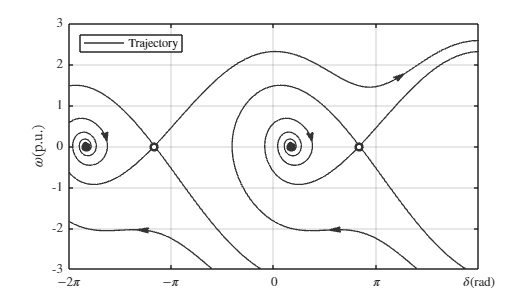

set(gcf, 'unit', 'centimeters', 'position', [0,0,14,8])
set(gca, 'ticklabelinterpreter', 'latex',...
         'xtick', -2*pi:pi:2*pi,...
         'xticklabels', {'$$-2\pi$$','$$-\pi$$',...
                         '$$0$$','$$\pi$$','$$\delta\mathrm{(rad)}$$'});
ylabel('$$\omega\mathrm{(p.u.)}$$', 'interpreter', 'latex');
legend({'Trajectory'}, 'Interpreter',"latex", 'location', 'northwest')

### More Information

If you have any questions about plotpp, please refer to the help doc, which contains the detailed definition of the input arguments:

help plotpp

  Help for plotpp:
 
  Parameter definitions:
  -- odefun: (required) this function must be a 2-dimension autonomous
             function with respect to (t, x).
  -- tspan: time span for ode computing, default value is 40;
  -- xLim: x-axis plot range, default value is [-5,5];
  -- yLim: y-axis plot range, default value is [-5,5];
  -- xPlotNum: trajectories that start/end from horizental border,
               default value is 4;
  -- yPlotNum: trajectories that start/end from vertical border,
               default value is 4;
  -- lineColor: color of lines and points, default is [0.1,0.1,0.1];
  -- quiverColor: color of quiver plots, default is [0.5,0.5,0.5];
 
 
  -- plotNonSaddleTrajectory: whether or not to plot non-saddle points
                              trajcetories, default value is true;
  -- plotEPs:    whether or not to plot equilibrium points (EPs),
                 default value is true;
  -- plotArrows: whether or not to plot arrows, default value is true;
  -- plo